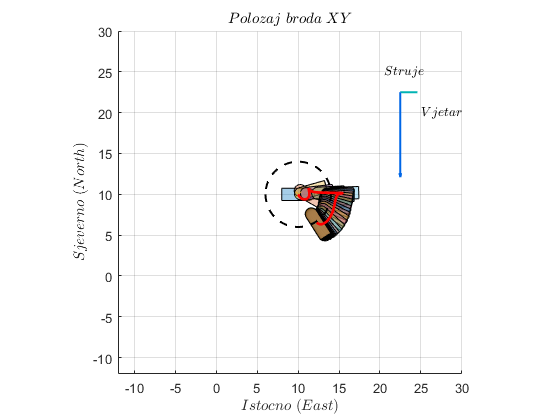


% Crtanje figure broda
x=[-0.75 -0.75 -0.75*cos(deg2rad(10))...
    -0.75*cos(deg2rad(20)) -0.75*cos(deg2rad(30))...
    -0.75*cos(deg2rad(40)) -0.75*cos(deg2rad(50))...
    -0.75*cos(deg2rad(60)) -0.75*cos(deg2rad(70))...
    -0.75*cos(deg2rad(80)) 0 ...
    0.75*cos(deg2rad(80)) 0.75*cos(deg2rad(70))...
    0.75*cos(deg2rad(60)) 0.75*cos(deg2rad(50))...
    0.75*cos(deg2rad(40)) 0.75*cos(deg2rad(30))...
    0.75*cos(deg2rad(20)) 0.75*cos(deg2rad(10))...
    0.75 0.75];
y=[-2 1.25 1.25+0.75*sin(deg2rad(10))...
    1.25+0.75*sin(deg2rad(20)) 1.25+0.75*sin(deg2rad(30))...
    1.25+0.75*sin(deg2rad(40)) 1.25+0.75*sin(deg2rad(50))...
    1.25+0.75*sin(deg2rad(60)) 1.25+0.75*sin(deg2rad(70))...
    1.25+0.75*sin(deg2rad(80)) 2 ...
    1.25+0.75*sin(deg2rad(80)) 1.25+0.75*sin(deg2rad(70))...
    1.25+0.75*sin(deg2rad(60)) 1.25+0.75*sin(deg2rad(50))...
    1.25+0.75*sin(deg2rad(40)) 1.25+0.75*sin(deg2rad(30))...
    1.25+0.75*sin(deg2rad(20)) 1.25+0.75*sin(deg2rad(10))...
    1.25 -2];
b=polyshape(x,y);

% Definiranje podataka iz simulacije
Kurs = out.PSI.Data;
Brzina_u = out.U.Data;
Brzina_v = out.V.Data;
Polozaj_E = out.E.Data;
Polozaj_N = out.N.Data;
Vrijeme = out.tout;
Rpm = out.RPM.Data;
Alfa = out.Alfa.Data;
Ex=out.e_x.Data;
Epsi=out.e_psi.Data;

%Crtanje gibanja broda u NED sustavu
figure(1)
for i=1:round(length(Vrijeme)/30):length(Vrijeme)
b1=translate(b,[Polozaj_E(i) Polozaj_N(i)]);
b2=rotate(b1,-Kurs(i),[Polozaj_E(i) Polozaj_N(i)]);
plot(b2)
hold on
end
pvec(22.5,22.5,7*V_c,gama_c+180,[0 0.7 0.7]," ",'-',1.5);
hold on
pvec(22.5,22.5,1.3*V_vj,gama_vjet+180,[0.0 0.4 0.9]," ",'-',1.5);
hold on
rectangle('Position',[E_c - r_o, N_c - r_o, r_o*2, r_o*2],'Curvature',[1,1],'LineWidth',1.5,'LineStyle',"--");
hold on
plot(10,10,'x')
hold on
text(20.5,25,"$ Struje $","Interpreter","latex")
text(25,20,"$ Vjetar $","Interpreter","latex")
grid on
title("$ Polozaj \ broda \ XY $","Interpreter","latex");
xlabel("$ Istocno \ (East) $", "Interpreter","latex");
ylabel("$ Sjeverno \ (North) $","Interpreter","latex");
plot(Polozaj_E,Polozaj_N,'r','LineWidth',2)
hold on
axis([-12 30 -12 30])

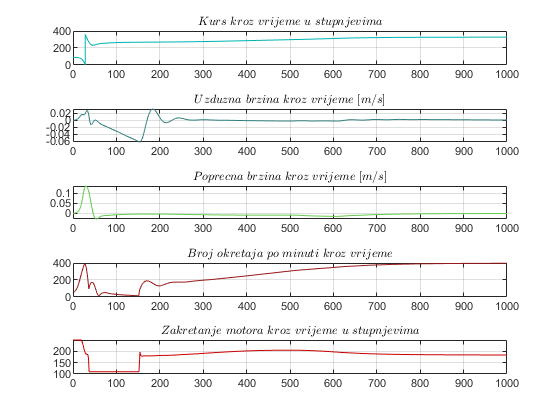

% 
% % Crtanje karakterističnih signala iz simulacije
figure(2)
tiledlayout(5,1)
nexttile
plot(Vrijeme,Kurs,'Color',[0 0.7 0.7])
title("$Kurs \ kroz \ vrijeme \ u \ stupnjevima$", "Interpreter","latex")
grid on
nexttile
plot(Vrijeme,Brzina_u,'Color',[0.2 0.5 0.5])
title("$Uzduzna \ brzina \ kroz \ vrijeme \ [m/s]$","Interpreter","latex")
grid on
nexttile
plot(Vrijeme,Brzina_v,'Color',[0.4 0.8 0.3])
title("$Poprecna \ brzina \ kroz \ vrijeme \ [m/s]$","Interpreter","latex")
grid on
nexttile
plot(Vrijeme,Rpm,'Color',[0.6 0.1 0.1])
title("$Broj \ okretaja \ po \ minuti \ kroz \ vrijeme$","Interpreter","latex")
grid on
nexttile
plot(Vrijeme,Alfa,'Color',[0.8 0 0])
title("$Zakretanje \ motora \ kroz \ vrijeme \ u \ stupnjevima$","Interpreter","latex")
grid on

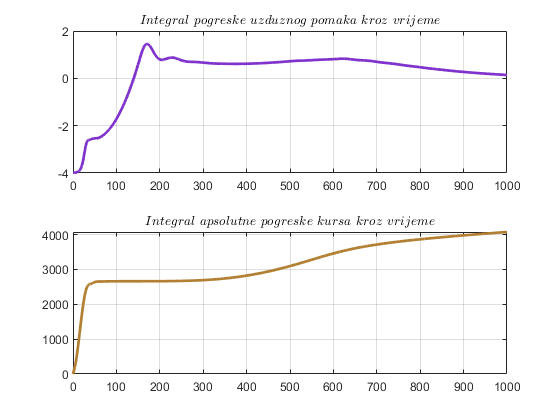


% Integralna pogreška kursa i udaljenost od kružnice
figure(3)
tiledlayout(2,1)
nexttile
plot(out.e_x.Time,Ex,'Color',[0.5 0.2 0.8],"LineWidth",2)
title("$Integral \ pogreske \ uzduznog \ pomaka \ kroz \ vrijeme$", "Interpreter","latex")
grid on
nexttile
plot(out.e_psi.Time,Epsi,'Color',[0.7 0.5 0.2],"LineWidth",2)
title("$Integral \ apsolutne \ pogreske \ kursa \ kroz \ vrijeme$", "Interpreter","latex")
grid on


%Kut upada struje na smjer broda ,razlika kurseva broda i struje
% gama = linspace(-180,180,100);

%Koeficijenti struja
% Cx=-0.4*cos(gama*pi/180).*abs(cos(gama*pi/180));
% Cy=0.6*sin(gama*pi/180).*abs(sin(gama*pi/180));
% Cn=0.1*sin(2*gama*pi/180);
% figure(1)
% plot(gama,Cx,'r','LineWidth',2)
% hold on
% plot(gama,Cy,'b','Linewidth',2)
% plot(gama,Cn,'g','Linewidth',2)
% grid on
% xlabel("Kut upada struje na smjer broda")
% title("Koeficijenti struja")
% legend("Cx","Cy","Cn")
% hold off

% Koeficijenti vjetra

% gama_vj = linspace(-180,180,100);
% Cx_vj=-0.6*cos(gama_vj*pi/180);
% Cy_vj=0.8*sin(gama_vj*pi/180);
% Cn_vj=0.1*sin(2*gama_vj*pi/180);

% figure(2)
% plot(gama_vj,Cx_vj,'r','LineWidth',2)
% hold on
% plot(gama_vj,Cy_vj,'b','Linewidth',2)
% plot(gama_vj,Cn_vj,'g','Linewidth',2)
% grid on
% xlabel("Kut upada vjetra na smjer broda")
% title("Koeficijenti vjetra")
% legend("Cx_v","Cy_v","Cn_v")
% hold off